%test galactic

format short % long for 15 sig figs, change to short for 4 sig figs

## SES

#### UTS*Area load cases 

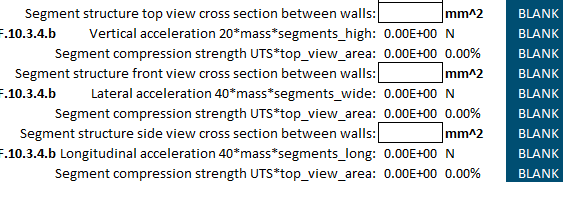

#### Module Volume

[https://enepaq.com/wp-content/uploads/2023/09/VTC6-Sony-Murata-Li-ion-Battery-Module-With-Temperature-Sensor-Datasheet-Tesla-Battery-Sponsorship-Formula-SAE-Electric-Formula-Student-Battery-Pack.pdf](https://enepaq.com/wp-content/uploads/2023/09/VTC6-Sony-Murata-Li-ion-Battery-Module-With-Temperature-Sensor-Datasheet-Tesla-Battery-Sponsorship-Formula-SAE-Electric-Formula-Student-Battery-Pack.pdf) 

EneModWidth = 20.13418951/1000%(m)

EneModWidth = 0.0201

EneSegHeight =  105.6/1000%(m)

EneSegHeight = 0.1056

EneModDepth = 69.5/1000%(m)

EneModDepth = 0.0695

ModuleWeight = 278/1000%kg

ModuleWeight = 0.2780

### Segment Dimensions

SegmentCasingHeight = EneSegHeight%m

SegmentCasingHeight = 0.1056

EneSegmentDepth = 6*EneModDepth%num moduleSs*moduleDepth*mmtoinches + flange added length - hole locatoin

EneSegmentDepth = 0.4170

EneSegmentWidth = EneModWidth * 4

EneSegmentWidth = 0.0805

garoliteThickness = (1/8)*25.4/1000%m

garoliteThickness = 0.0032

SegmentModulesWeight = ModuleWeight*23%kg

SegmentModulesWeight = 6.3940

### Segment Cross Sectional Areas

TopCrossSecArea = EneSegmentDepth*garoliteThickness*2

TopCrossSecArea = 0.0026

WidthCrossSecArea = EneSegmentDepth*garoliteThickness*2

WidthCrossSecArea = 0.0026

DepthCrossSecArea = EneSegmentWidth*garoliteThickness*2 + EneSegHeight*garoliteThickness*2

DepthCrossSecArea = 0.0012

airHoleDia = 8/1000;%m

### Tab Gluing Strength

Pload = 9.8*20*SegmentModulesWeight

Pload = 1.2532e+03

insetlength = 26.75/1000%m

insetlength = 0.0267

bolttosegmentlength = 14/1000%m

bolttosegmentlength = 0.0140

L1 = 14/1000%m

L1 = 0.0140

L2 = 40.75/1000%m

L2 = 0.0408

P1 = -(Pload*L2)/(L2-L1)

P1 = -1.9091e+03

P2 = (Pload*L1)/(L2-L1)

P2 = 655.8929

Mc = Pload*L2 - P1*(L2-L1)

Mc = 102.1378

Medge = -Pload*L1 + Mc

Medge = 84.5926

Stress_bending = (Medge*(garoliteThickness/2))/(4*garoliteThickness*garoliteThickness^3)/12

Stress_bending = 2.7532e+07

%Stress_shear = Pload/

### Lid (Polycarbonate) Properties

polycarbonateThickness = 1/4*25.4/1000

polycarbonateThickness = 0.0063

PCBendingStrength = 90*10^6%Pa

PCBendingStrength = 90000000

### Lid Bending

Ma = (Pload*EneSegmentDepth^2)/12

Ma = 18.1602

Stress_bending = (Ma*(polycarbonateThickness/2))/(polycarbonateThickness^3*(EneSegmentWidth)/12)

Stress_bending = 3.3553e+07


%stress concentration factor

%approximate rectangular hole as a circle with d = 2r where r is the radius
%of fillet

%hole diameter
d = 8/1000%mm

d = 0.0080

%section width
w = EneSegmentWidth

w = 0.0805

%section thickness
h = polycarbonateThickness

h = 0.0063


d/h

ans = 1.2598

d/w

ans = 0.0993


%From Norton Appendix C
k = 2.0

k = 2


SF = (PCBendingStrength)/(k*Stress_bending)

SF = 1.3412

### Base Bending

Ma = (Pload*EneSegmentWidth^2)/12

Ma = 0.6774

Stress_bending = (Ma*(garoliteThickness/2))/(garoliteThickness^3*(EneSegmentWidth)/12)

Stress_bending = 5.0062e+06


SF = (PCBendingStrength)/(Stress_bending)

SF = 17.9778

### Short Side Bending

Ma = (Pload*EneSegmentWidth^2)/12

Ma = 0.6774

Stress_bending = (Ma*(garoliteThickness/2))/(garoliteThickness^3*(EneSegmentWidth)/12)

Stress_bending = 5.0062e+06


%stress concentration factor

%hole diameter
d = 8/1000%mm

d = 0.0080

%section width
w = EneSegmentWidth

w = 0.0805

%section thickness
h = garoliteThickness

h = 0.0032


d/h

ans = 2.5197

d/w

ans = 0.0993


%From Norton Appendix C
k = 1.7

k = 1.7000


SF = (PCBendingStrength)/(k*Stress_bending)

SF = 10.5752

### Garolite Properties

psiTopPascal = 6894.76;
garoliteStrength = 38000*psiTopPascal;%262,000,000pa
garoliteFlexuralModulus = 2400* 1000 * psiTopPascal

garoliteFlexuralModulus = 1.6547e+10

### Segment Forces and Stresses

TopCrossSecForce = SegmentModulesWeight*20*9.8%in newtons

TopCrossSecForce = 1.2532e+03

WidthCrossSecForce = 6*SegmentModulesWeight*40*9.8;%in newtons
DepthCrossSecForce = SegmentModulesWeight * 40 * 9.8;

TopStress = TopCrossSecForce/TopCrossSecArea

TopStress = 4.7328e+05

WidthStress = WidthCrossSecForce/WidthCrossSecArea

WidthStress = 5.6794e+06

DepthStress = DepthCrossSecForce/DepthCrossSecArea

DepthStress = 2.1206e+06

SafetyFactorCasing = garoliteStrength/WidthStress

SafetyFactorCasing = 46.1320

### Vertical Minimum Column Properties

vmincolumnlength = EneSegmentWidth*1000%mm

vmincolumnlength = 80.5368

vmincolumnarea = (garoliteThickness*EneSegHeight - 5*airHoleDia*garoliteThickness)*1000^2%mm^2

vmincolumnarea = 208.2800

vmincolumnMOI = ((garoliteThickness^3*(EneSegmentWidth-5*airHoleDia))/12)*1000^4%mm^4

vmincolumnMOI = 108.1182

vPcrEuler = (pi^2*garoliteFlexuralModulus*vmincolumnMOI)/vmincolumnlength^2

vPcrEuler = 2.7223e+09

stress_compressive = TopCrossSecForce/(vmincolumnarea/1000^2)

stress_compressive = 6.0170e+06

### Lateral Minimum Column Properties

lmincolumnlength = EneSegmentDepth*1000%mm

lmincolumnlength = 417.0000

lmincolumnarea = (garoliteThickness*(EneSegmentWidth+2*garoliteThickness))*1000^2%mm^2

lmincolumnarea = 275.8655

lmincolumnMOI = ((garoliteThickness^3*(EneSegmentWidth+2*garoliteThickness))/12)*1000^4%mm^4

lmincolumnMOI = 231.7414

### Bolt calculations

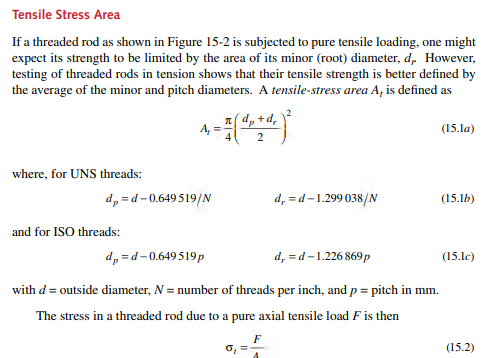

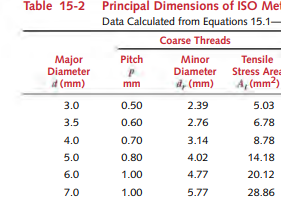

dia = 6;
pitch = 1;
diaPitch = dia - 0.649519*pitch;%mm 
diaRoot = dia - 1.226869*pitch ;%mm
AreaBoltTensile = pi/4*((diaPitch+diaRoot)/2)^2;%in mm^2
ABTMeters = AreaBoltTensile/1000000;%Converts to Meters
exampleGr5Tensile = 827370875;%Converted from psi
MaxTensileForFastener = exampleGr5Tensile*ABTMeters %newtons

MaxTensileForFastener = 1.6649e+04

SafetyFactorBoltTension = MaxTensileForFastener*2/TopCrossSecForce

SafetyFactorBoltTension = 26.5707

SafetyFactorVoltShear = WidthCrossSecForce*12/MaxTensileForFastener

SafetyFactorVoltShear = 10.8390

### Tear out 

[https://laminatedplastics.com/g-10.pdf](https://laminatedplastics.com/g-10.pdf) 

BoltDistanceFromEdge = 8/1000;%mm  realistic distance from edge
maxTearoutForce = BoltDistanceFromEdge*garoliteThickness*garoliteStrength

maxTearoutForce = 6.6548e+03

### Flange Bonding

fr4BondStrength = 2200*psiTopPascal;
MinFlangeBondArea = DepthCrossSecForce/fr4BondStrength

MinFlangeBondArea = 1.6524e-04

DepthRestrictingBondArea = garoliteThickness * 80/1000

DepthRestrictingBondArea = 2.5400e-04

SideBondArea = 0.02* garoliteThickness*2

SideBondArea = 1.2700e-04

bondMaxForce = fr4BondStrength * (DepthRestrictingBondArea + SideBondArea)

bondMaxForce = 5.7792e+03

### Lid Deflection from 20g Loading

Packload = TopCrossSecForce ;
EneLidSegmentDepth = 6*EneModDepth + 0.082 -0.022;%
vmax = Packload * (EneLidSegmentDepth^4)/384/(garoliteFlexuralModulus)/((0.08*garoliteThickness^3)/12);

vmax = 0.0479

## Euler-Johnson buckling limits

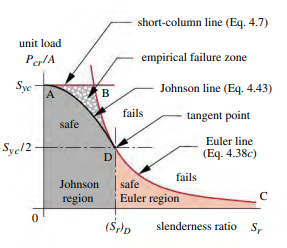

%segment casing constructed of G10/FR4 Garolite with following properties
Sy = 2.41*10^8 %Pa

Sy = 241000000

E = 1.52*10^10 %Pa

E = 1.5200e+10

## Vertical Acceleration

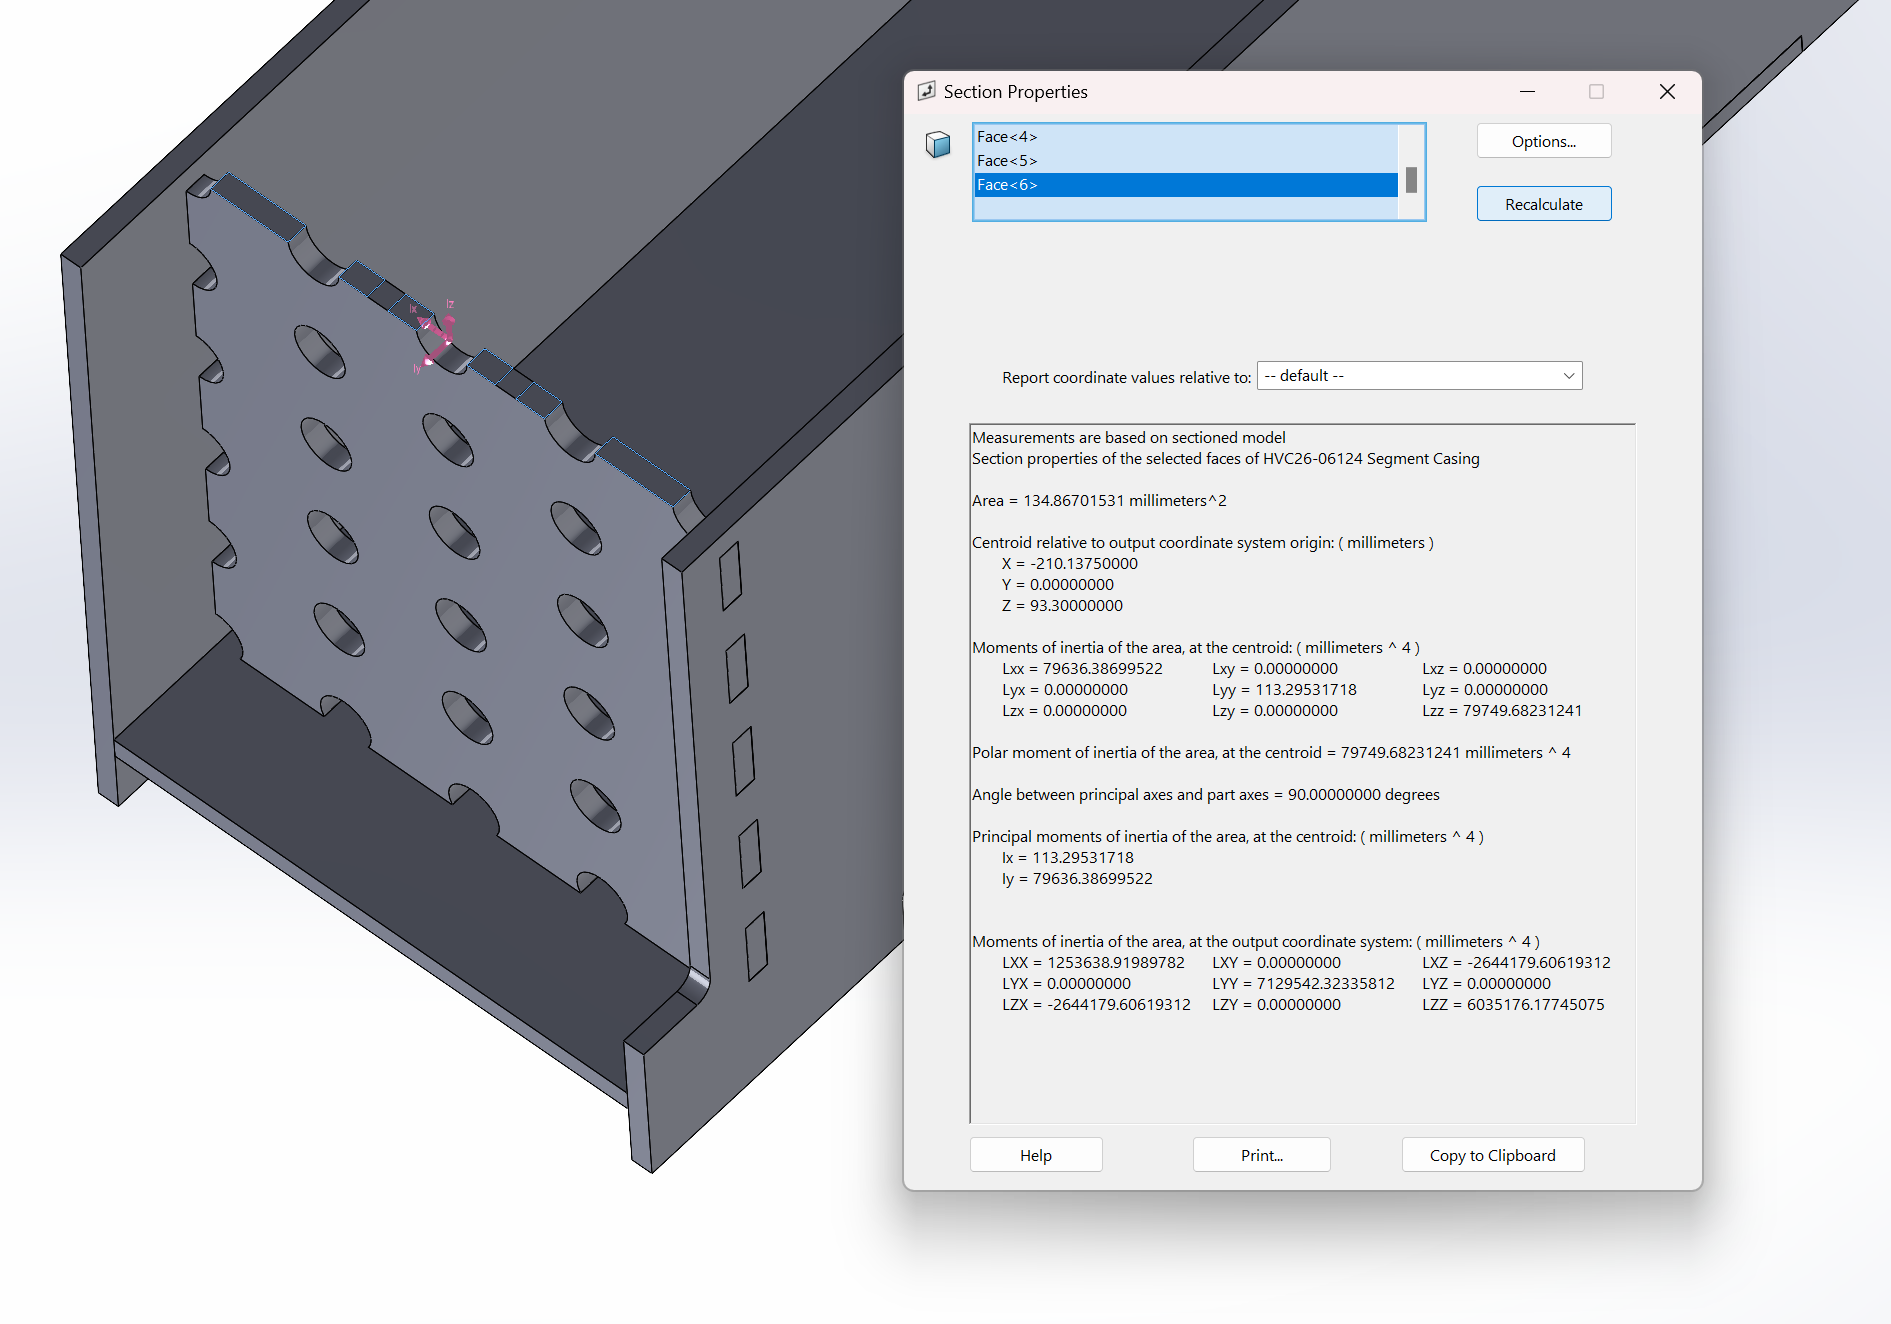

%Number of columns in minimum top view cross section
n = 4;

n = 4

%column length
l = 119/1000; %m

l = 0.1190

%top view cross-sectional area of minimum column
A = 134.87/1000^2; %m^2

A = 1.3487e-04

%top view MOI of minimum column
I = 113.3/1000^4; %m^4

I = 1.1330e-10


Le = .5*l; %fixed-fixed column

Le = 0.0595

r = sqrt(I/A);

r = 9.1655e-04


%Slenderness Ratio
Sr = Le/r;

Sr = 64.9172


%if this slenderness ratio is greater than the slenderness ratio above, use
%johnson buckling equation, otherwise use Euler buckling equation
SrD = pi*sqrt((2*E)/(Sy));

SrD = 35.2840


MaxForceEuler = n*((pi^2*E*A)/(Le/r)^2);

MaxForceEuler = 1.9204e+04


%number of segments vertically stacked
ns = 1;

ns = 1

MaxForce = ns*20*9.82*SegmentModulesWeight; %N

MaxForce = 1.2558e+03


SF = (MaxForceEuler/MaxForce);

SF = 15.2927

## Lateral Acceleration

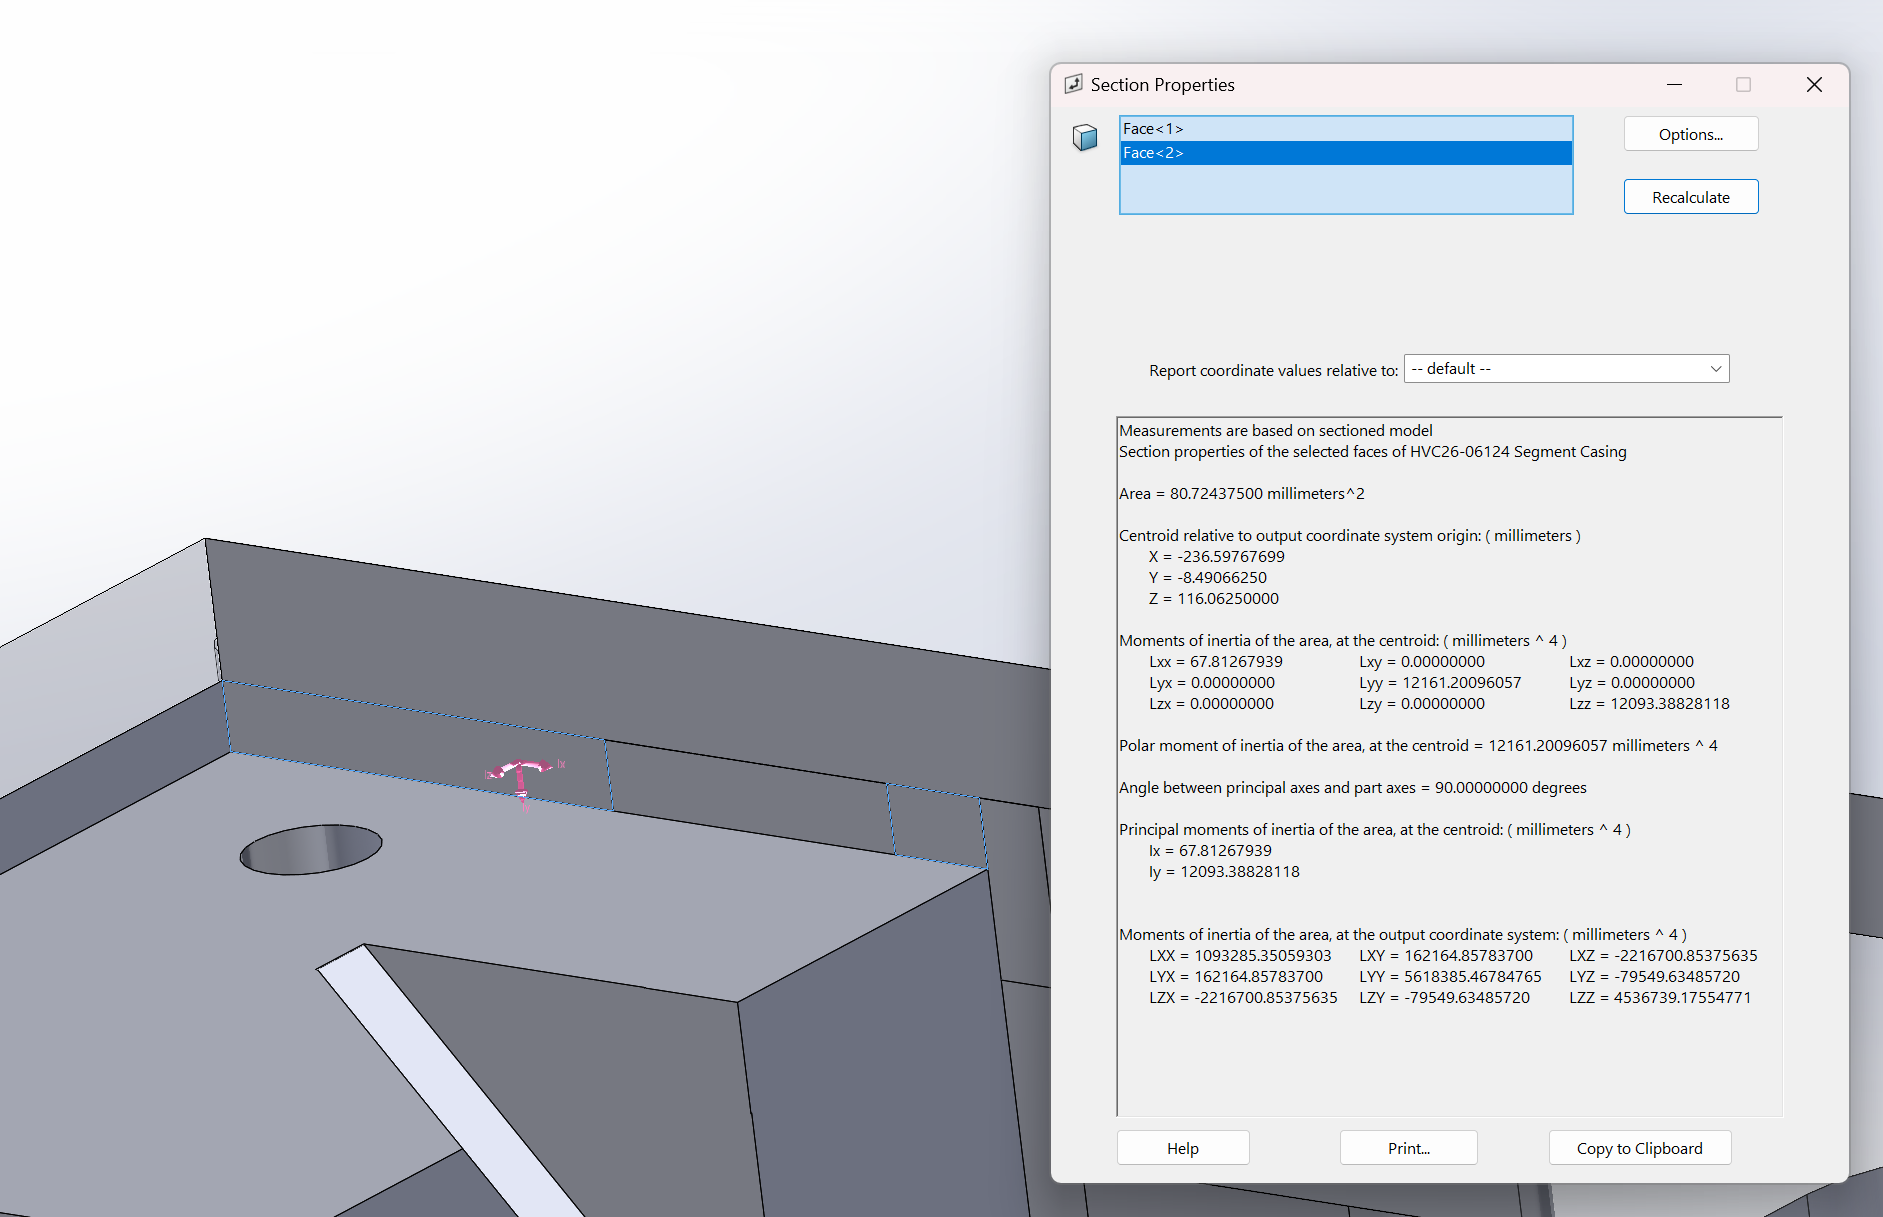

%Number of columns in minimum side view cross section
n = 5

n = 5

%column length
l = 84.6/1000 %m

l = 0.0846

%side view cross-sectional area of minimum column
A = 80.72/1000^2 %m^2

A = 8.0720e-05

%side view MOI of minimum column
I = 67.8/1000^4 %m^4

I = 6.7800e-11


Le = .5*l %fixed-fixed column

Le = 0.0423

r = sqrt(I/A)

r = 9.1648e-04


%Slenderness Ratio
Sr = Le/r

Sr = 46.1547


%if this slenderness ratio is greater than the slenderness ratio above, use
%johnson buckling equation, otherwise use Euler buckling equation
SrD = pi*sqrt((2*E)/(Sy))

SrD = 35.2840


MaxForceEuler = n*((pi^2*E*A)/(Le/r)^2)

MaxForceEuler = 2.8423e+04


%number of segments vertically stacked
ns = 6

ns = 6

MaxForce = ns*20*9.82*SegmentModulesWeight %N

MaxForce = 7.5347e+03


SF = (MaxForceEuler/MaxForce)

SF = 3.7722

## Longitudinal Acceleration

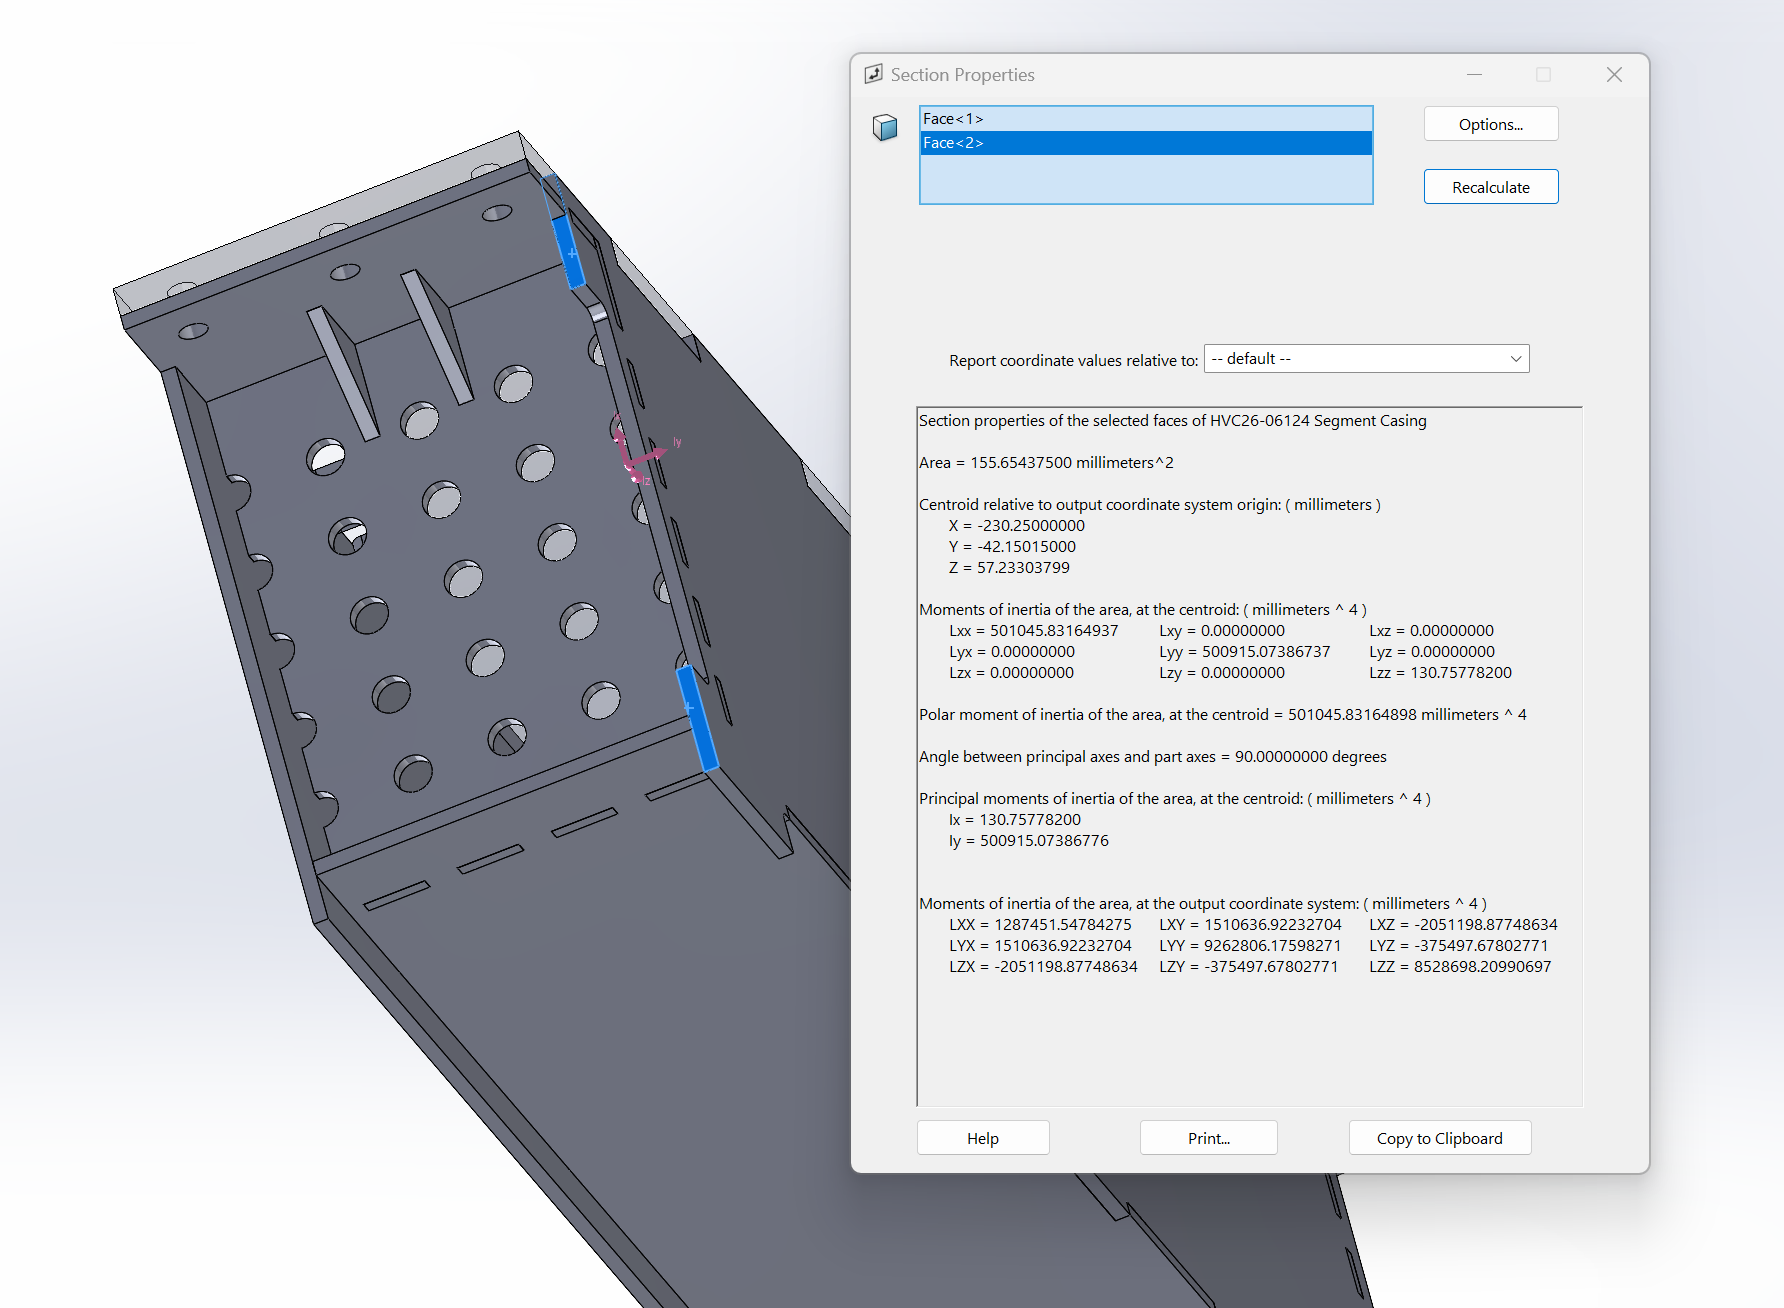

%Number of columns in minimum front view cross section
n = 4

n = 4

%column length
l = 460.5/1000 %m

l = 0.4605

%front view cross-sectional area of minimum column
A = 155.65/1000^2 %m^2

A = 1.5565e-04

%front view MOI of minimum column
I = 130.76/1000^4 %m^4

I = 1.3076e-10


Le = .5*l %fixed-fixed column

Le = 0.2303

r = sqrt(I/A)

r = 9.1656e-04


%Slenderness Ratio
Sr = Le/r

Sr = 251.2099


%if this slenderness ratio is greater than the slenderness ratio above, use
%johnson buckling equation, otherwise use Euler buckling equation
SrD = pi*sqrt((2*E)/(Sy))

SrD = 35.2840


MaxForceEuler = n*((pi^2*E*A)/(Le/r)^2)

MaxForceEuler = 1.4801e+03


%number of segments vertically stacked
ns = 1

ns = 1

MaxForce = ns*20*9.82*SegmentModulesWeight %N

MaxForce = 1.2558e+03


SF = (MaxForceEuler/MaxForce)

SF = 1.1786

### Passive Thermal Properties

SurfaceArea = EneSegmentDepth*EneSegmentWidth*2 + EneSegHeight*EneSegmentDepth*2;
heatFluxPerC = 1/garoliteThickness * 0.288 * SurfaceArea

heatFluxPerC = 14.0814

MomentOfInertiaSideWalls = 2*( (EneSegmentWidth/2+garoliteThickness/2)^2 * garoliteThickness*(EneSegHeight+(2*garoliteThickness))) + (garoliteThickness^3*SegmentCasingHeight/12)

MomentOfInertiaSideWalls = 1.2457e-06

% half width to get to walls + half of garolite thickness = centroid
% distance away, * area sidewall + garolite thickness^3(height) * segment height(width) 

MomentOfInertiaBottom = (garoliteThickness/2 + EneSegHeight/2)^2 * garoliteThickness*EneSegmentWidth + (garoliteThickness^3*EneSegmentWidth/12)

MomentOfInertiaBottom = 7.5659e-07

MomentOfInertiaLid = (garoliteThickness/2 + EneSegHeight/2+(15/1000))^2 * garoliteThickness*EneSegmentWidth + (garoliteThickness^3*EneSegmentWidth/12)

MomentOfInertiaLid = 1.2313e-06


ixx = MomentOfInertiaLid + MomentOfInertiaBottom + MomentOfInertiaSideWalls

ixx = 3.2336e-06

RadiusOfGyration = sqrt(ixx/DepthCrossSecArea)

RadiusOfGyration = 0.0523


SlendernessRatioCasing = EneSegmentDepth/RadiusOfGyration

SlendernessRatioCasing = 7.9725

SlendernessRatioForHalfStrength = pi*sqrt(2*garoliteFlexuralModulus/garoliteStrength)

SlendernessRatioForHalfStrength = 35.3085

MaxForceJohnson = DepthCrossSecArea *(garoliteStrength-(1/garoliteFlexuralModulus *(garoliteStrength*SlendernessRatioCasing/2/pi)^2))

MaxForceJohnson = 3.0178e+05

MaxForceEuler = (pi^2*garoliteFlexuralModulus*DepthCrossSecArea)/(SlendernessRatioCasing)^2

MaxForceEuler = 3.0370e+06